# Antenna Pattern Collection Lab

In this lab, we capture the antenna pattern of the Phaser using a different approach than the Antenna Pattern Lab. Here, we leave the beam steered directly toward boresight and try to rotate the Phaser to collect the antenna pattern. This is how the antenna pattern would be collected in reality.

Before running this lab, ensure that you have already collected the calibration weights using the "Calibrate Antenna" livescript.

## Setup

First, put the HB100 transmitter as close to boresight as possible. For this lab to work, the transmitter has to start at boresight.

Run the following to clear the workspace.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

We also load the calibration weights which are applied so that the beam pattern matches our expectations.

load('CalibrationWeights.mat','calibrationweights');

We also load the frequency of the transmitter being used.

load('HB100_Fc.mat','fc_hb100');

### Create Antenna Interactor

The antenna interactor object helps us to interact with the phaser board to steer the beam and collect data. Create this object so that we can control the antenna.

ai = AntennaInteractor(fc_hb100,calibrationweights);

### Create Antenna Model

In order to generate amplitudes and phases to change the antenna pattern behavior, we need to have an approximate model of the antenna array. The Phaser antenna array is made up of two four-element uniform linear arrays (ULA). The antenna element spacing is set for a 1/2 wavelength at a frequency of 10.7 GHz. This gives a spacing between receive array elements of 14 mm.  We create this antenna model below.

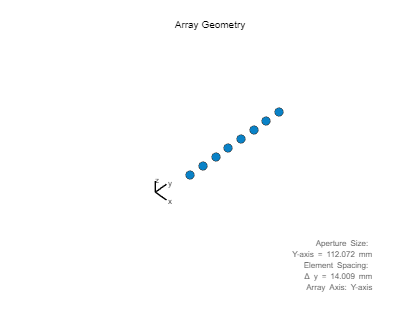

lambda = freq2wavelen(10.7e9);
spacing = lambda/2;
array = phased.ULA(NumElements=8,ElementSpacing=spacing);
elementLocation = array.getElementPosition();
viewArray(array);

## Collect Antenna Pattern

In this case we leave the beam always steered towards boresight. We capture the amplitude of the received signal while asking you to rotate the phaser so that the HB100 transmitter is located at different angles. Try to rotate the Phaser so that the HB100 is at the correct angle and see how the antenna pattern changes as a function of azimuth angle.

In reality, this kind of antenna pattern collection would happen with precise lab instruments that know the exact measurement angle.

Try running this script and rotating the Phaser so that the HB100 is at the expected angle.

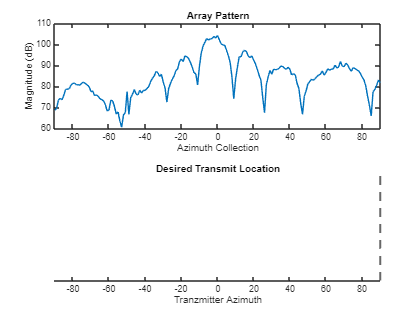

% Steering angle
steerAngle = 0;

% Initialize the data collection values
azAngles = -90:90;
nAngles = length(azAngles);
pattern = nan(1,nAngles);

% Create a plot for the antenna pattern and for the desired transmitter
% angle
f = tiledlayout(2,1);
patAx = nexttile(f);
azAx = nexttile(f);

% Create a line on the pattern axes to plot the pattern
patLine = plot(patAx,azAngles,pattern);
xlim(patAx,[-90 90]);
title(patAx,'Array Pattern');
xlabel(patAx,'Azimuth Collection');
ylabel(patAx,'Magnitude (dB)');

% Create a line on the azimuth axes to plot the desired tx location
azLine = xline(azAx,azAngles(1),LineStyle='--',LineWidth=2);
xlim(azAx,[-90 90]);
title(azAx,'Desired Transmit Location');
xlabel(azAx,'Tranzmitter Azimuth');
azAx.YAxis.Visible = false;

% Collect data at each angle, and plot pattern
for i = 1:nAngles
    % Set current angle
    azLine.Value = azAngles(i);
    drawnow;

    % Collect data steering to boresight
    steerweights = steervec(elementLocation/freq2wavelen(fc_hb100),[steerAngle;0]);
    analogsteer = analogWeightsCalAdjustment([steerweights(1:4) steerweights(5:8)],calibrationweights.AnalogWeights);
    data = ai.steerAnalog(analogsteer);
    digitalsteer = digitalWeightsCalAdjustment([1;1],calibrationweights.DigitalWeights);
    data = data * conj(digitalsteer);

    % Plot the updated pattern
    pattern(i) = mag2db(helperGetAmplitude(data));
    patLine.YData = pattern;
    drawnow;
end

% Perform cleanup
cleanup(ai);